Pre-Emphasis

[y,fs]=audioread("C:\Users\Lenovo\Documents\MATLAB\DSP\Digital-Signal-Processing\audio_files\one.wav")

y =     0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002


fs = 44100

length_of_signal=length(y)

length_of_signal = 112852

pre_emphasised=zeros(size(y))

pre_emphasised =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


N=length_of_signal

N = 112852

filter_coeff=[1,-0.95];

for i=2:N
    pre_emphasised(i)=y(i)*filter_coeff(1)+y(i-1)*filter_coeff(2);
end

plot(y)

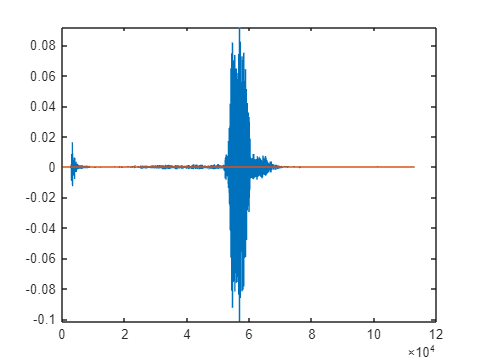

plot(pre_emphasised)

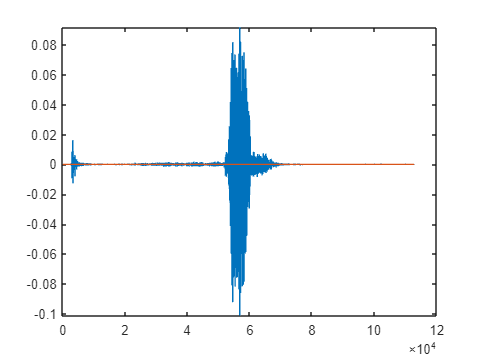

X = fft(y);

% Calculate the frequency axis
f = linspace(-fs/2, fs/2, length(X));

% Plot the magnitude spectrum
figure;
plot(f, fftshift(abs(X)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Audio Signal');

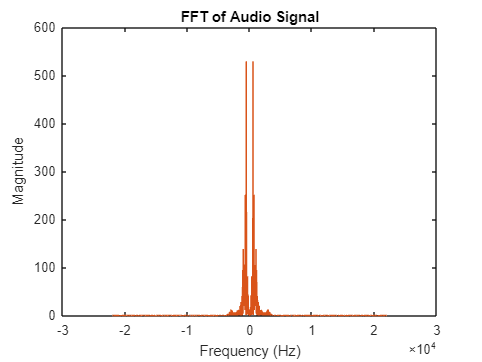


X = fft(pre_emphasised);

% Calculate the frequency axis
f = linspace(-fs/2, fs/2, length(X));

% Plot the magnitude spectrum
figure;
plot(f, fftshift(abs(X)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Audio Signal');

sound(pre_emphasised,fs)

Noise-Gate

threshold=0.01

threshold = 0.0100

filtered_signal = pre_emphasised;
filtered_signal(abs(pre_emphasised) < threshold) = 0;

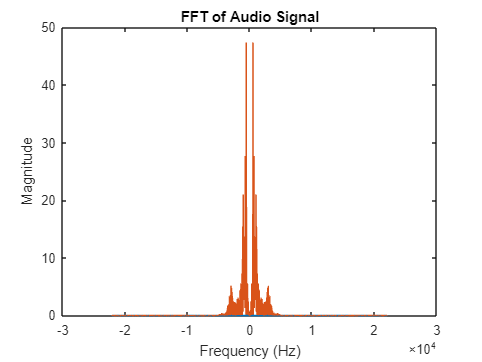

t = (0:length(y)-1) / fs;
plot(t,filtered_signal)

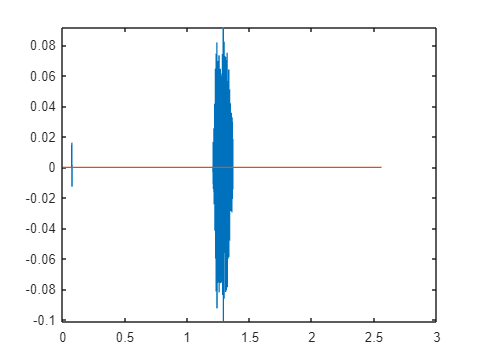


X = fft(filtered_signal);

% Calculate the frequency axis
f = linspace(-fs/2, fs/2, length(X));

% Plot the magnitude spectrum
figure;
plot(f, fftshift(abs(X)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Audio Signal');

sound(filtered_signal,fs)

audiowrite('original.wav',y,fs)
audiowrite('pre_empasised.wav',pre_emphasised,fs)
audiowrite('noise_removed.wav',filtered_signal,fs)

Zero-Allignment

audio=detrend(filtered_signal)

audio =     0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0


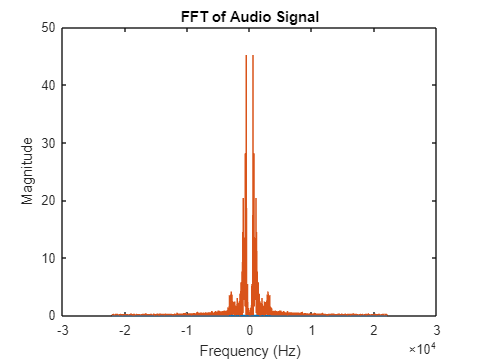

plot(t,audio)

% % Specify the input audio file
% inputFile = 'one.wav';
% 
% % Read the audio file
% [x, fs] = audioread(inputFile);
% 
% % Specify the duration of each chunk in seconds
% chunkDuration = 1;  % adjust this according to your needs
% 
% % Calculate the number of samples in each chunk
% chunkSize = round(chunkDuration * fs);
% 
% % Calculate the number of chunks
% numChunks = ceil(length(x) / chunkSize);
% 
% % Loop through the audio and write each chunk to a separate file
% for i = 1:numChunks
%     % Determine the start and end indices for the current chunk
%     startIndex = (i - 1) * chunkSize + 1;
%     endIndex = min(i * chunkSize, length(x));
% 
%     % Extract the current chunk
%     currentChunk = x(startIndex:endIndex);
% 
%     % Create a filename for the current chunk (e.g., chunk1.wav, chunk2.wav, etc.)
%     outputFileName = sprintf('chunk%d.wav', i);
% 
%     % Write the current chunk to a separate file
%     audiowrite(outputFileName, currentChunk, fs);
% % end


inputFile = 'noise_removed.wav';
[x, fs] = audioread(inputFile);

frameDuration = 0.2;
overlapRatio = 1.0;
frameLength = 256;

frameSize = round(frameDuration * fs);
overlapSize = round(frameLength * overlapRatio);

x = x(:);

frames = buffer(x, frameSize, overlapSize, 'nodelay');

numFrames = size(frames, 2);
for i = 1:numFrames
    currentFrame = frames(:, i);
    outputFileName = sprintf('frame%d.wav', i);
    audiowrite(outputFileName, currentFrame, fs);
end


W(N)=0.54-0.46*cos(2*pi*N/(N-1))

W =     0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0801    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0803    0.0803    0.0803


inputFile ='noise_removed.wav';
[x, fs] = audioread(inputFile);

% Loop through the frames and process them as needed
numFrames = size(frames, 2)

numFrames = 27

for i = 1:numFrames
    currentFrame =sprintf('frame%d.wav', i)
    [x,fs]=audioread(currentFrame)
    N=length(x);
    n=(0:N-1);
    W=0.54-0.46*cos(2*pi*n/(N-1));
    windowed=x.*W;
    y=fft(windowed,512);
    y=y(1:257)
    fmel=2595*log10(1+(f/700))
end

currentFrame = 'frame1.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame2.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame3.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame4.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame5.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame6.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame7.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame8.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =    0.0125 + 0.0000i   0.0054 + 0.0002i   0.0143 - 0.0035i   0.0024 + 0.0015i   0.0290 - 0.0015i   0.0095 - 0.0217i   0.0229 - 0.0176i  -0.0076 - 0.0506i  -0.0229 - 0.0155i  -0.0269 - 0.0278i  -0.0412 + 0.0122i  -0.0117 + 0.0087i  -0.0215 + 0.0166i   0.0009 + 0.0147i  -0.0080 + 0.0092i  -0.0011 + 0.0101i  -0.0058 + 0.0124i   0.0019 + 0.0090i  -0.0077 + 0.0179i   0.0146 + 0.0172i   0.0018 + 0.0144i   0.0317 + 0.0191i   0.0177 - 0.0112i   0.0234 + 0.0024i   0.0140 - 0.0293i  -0.0031 - 0.0053i   0.0071 - 0.0181i  -0.0105 - 0.0062i   0.0034 - 0.0076i  -0.0089 - 0.0069i  -0.0030 - 0.0021i  -0.0034 + 0.0015i   0.0050 - 0.0050i  -0.0017 - 0.0050i   0.0033 - 0.0167i  -0.0239 - 0.0122i  -0.0124 + 0.0023i  -0.0265 + 0.0046i  -0.0030 + 0.0284i   0.0031 + 0.0060i   0.0058 + 0.0171i   0.0118 - 0.0048i  -0.0033 + 0.0039i   0.0069 + 0.0016i   0.0006 + 0.0022i   0.0070 + 0.0004i   0.0031 - 0.0026i   0.0005 - 0.0057i  -0.0044 + 0.0023i   0.0026 - 0.0009i


fmel = 4.6870e+03

currentFrame = 'frame9.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame10.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame11.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame12.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame13.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame14.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame15.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame16.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame17.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame18.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame19.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame20.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame21.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame22.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame23.wav'

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame24.wav'

x = 8820×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y = 1×257
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame25.wav'

x = 8820×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y = 1×257
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame26.wav'

x = 8820×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y = 1×257
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03

currentFrame = 'frame27.wav'

x = 8820×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

y = 1×257
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fmel = 4.6870e+03